% % Папка для хранения кадров
% workingDir = 'W:\MATLAB\vkr\';
% 
% % Загрузка видео
% v = VideoReader('W:\MATLAB\vkr\test2.ts');
% 
% % Создание последовательности кадров
% ii = 1;
% while hasFrame(v)
%     I = readFrame(v);
%     filename = [sprintf('%03d',ii) '.jpg'];
%     fullname = fullfile(workingDir,'images_eng',filename);
%     imwrite(I,fullname)
%     
%     % Обрезка изображения под бегущую строку
%     I2 = imread("W:\MATLAB\vkr\images_eng\001.jpg");
%     I3 = imcrop(I2,[0 506 720 70]);
% %    I3 = imcrop(I2,[0 290 640 70]);
%     filename2 = [sprintf('%03d',ii) '.jpg'];
%     
%     % Преобразование в ЧБ
%     I4 = colouredToGray(I3);
%     % filename2 = '260.jpg';
%     fullname2 = fullfile(workingDir,'images2',filename2);
%     imwrite(I4,fullname2)
%     ii = ii+1;
% end
% 
% subplot(1,2,1)
% imshow(I2)
% title('Original Image')
% subplot(1,2,2)
% imshow(I4)
% title('Resulting Image')

% Поиск областей с текстом
I5 = imread('W:\MATLAB\vkr\images2\001.jpg');
ocrResults = ocr(I5)

ocrResults =   ocrText with properties:

                      Text: ' ↵↵WORLD NEWS 3' CGM§lEH'§S IKEA FGBHDER IHGVAR KAMF↵.1-↵&-↵↵'
    CharacterBoundingBoxes: [61×4 double]
      CharacterConfidences: [61×1 single]
                     Words: {11×1 cell}
         WordBoundingBoxes: [11×4 double]
           WordConfidences: [11×1 single]


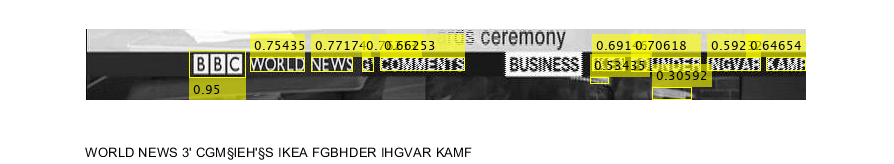

% Отображение областей с текстовой информацией
Iocr = insertObjectAnnotation(I5, 'rectangle', ...
    ocrResults.WordBoundingBoxes, ...
    ocrResults.WordConfidences);
recognizedText = ocrResults.Text;    
figure; imshow(Iocr);
     text(0, 140, recognizedText, 'BackgroundColor', [1 1 1]);